# Data Structures in MATLAB

In the world of "big data", processing large amounts of data efficiently and accurately is vital. MATLAB stores (and processes) data in a variety of ways. We have looked at numeric, char, string, and cell arrays for example, but MATLAB has numerous methods of storing a variety of different data types together. Let's look at two of them.

Please look at another example that is accessible through any MATLAB installation by executing:

openExample('matlab/AdvantagesOfUsingTablesExample')

ans = 'C:\Users\Tom K\Google Drive\Programs\courses\main\MATLABNotebooks\data'

And look at structures in a different context at [https://www.mathworks.com/help/matlab/matlab_prog/ways-to-organize-data-in-structure-arrays.html](https://www.mathworks.com/help/matlab/matlab_prog/ways-to-organize-data-in-structure-arrays.html)

## Tables

In MATLAB, a table is an array with named columns which can contain different data types. The function `readtable` reads data from a file and puts it in names columns. The default names are quite uninformative: `Var1`, `Var2`, `Var3`, ... , but you can change those manually or with the first row of the table. 

You can create a table from arrays of the same size with 

but it is easier to import data from a file. Let's look at the file `SatelliteDatabase.txt` in the data folder under the main github repository. 

#### Side Note on File Paths

MATLAB's current working directory is given by

pwd

The following code will construct an absolute path to the directory 1 level above the current directory

[path,fold] = fileparts(pwd);

C:\Users\Tom K\Google Drive\Programs\courses\main\MATLABNotebooks


disp(path)

data


disp(fold)

You can construct a path to a folder 1 level down from the current directory. Assuming that you are running this notebook in the main repository - a relative path of "main/MATLABNotebooks", the following will construct an absolute path to the data file we want

full = fullfile(pwd,'SatelliteDatabase.txt')

full = 'C:\Users\Tom K\Google Drive\Programs\courses\main\MATLABNotebooks\data\SatelliteDatabase.txt'

satdata = readtable(full)

satdata = 1099×8 table
          Name              Country                 Purpose              Altitude    Period     Mass    Year    Lifetime
    ________________    _______________    __________________________    ________    _______    ____    ____    ________

    {'Aalto-1'     }    {'Finland'    }    {'Technology Development'}       517         94.7       5    2017        2   
    {'ABS-2'       }    {'NR'         }    {'Communications'        }     35793      1436.03    6330    2014       15   
    {'ABS-2A'      }    {'NR (12/16)' }    {'Communications'        }     35700       1436.1    1800    2016       15   
    {'ABS-3A'      }    {'NR'         }    {'Communications'        }     35803         1436    200

Note how readtable recognized the first row as the column headers!

You access the elements of the table using *dot notation *and the traditional indexing in MATLAB

satdata.Purpose{90:101}

ans = 'Communications'

ans = 'Communications'

ans = 'Communications'

ans = 'Communications'

ans = 'Communications'

ans = 'Earth Observation'

ans = 'Earth Observation'

ans = 'Technology Development'

ans = 'Technology Development'

ans = 'Navigation/Global Positioning'

ans = 'Navigation/Global Positioning'

ans = 'Navigation/Global Positioning'

satdata.Name(satdata.Lifetime>10)

ans = 521×1 cell array
    {'ABS-2'       }
    {'ABS-2A'      }
    {'ABS-3A'      }
    {'ABS-4'       }
    {'ABS-6'       }
    {'ABS-7'       }
    {'USA 235'     }
    {'USA 246'     }
    {'Eutelsat 28B'}
    {'Al Yah-3'    }
    {'Alcomsat'    }
    {'Amazonas-2'  }
    {'Amazonas-3'  }
    {'Amazonas-4A' }
    {'Amazonas-5'  }
    {'AMC-1'       }
    {'AMC-10'      }
    {'AMC-11'      }
    {'AMC-15'      }
    {'AMC-16'      }
    {'AMC-18'      }
    {'AMC-2'       }
    {'AMC-21'      }
    {'AMC-4'       }
    {'AMC-6'       }
    {'AMC-7'       }
    {'AMC-8'       }
    {'Anik F1'     }
    {'Anik F1R'    }
    {'Anik F2'     }


sum(string(satdata.Country)=="Brazil")

ans =     10


You can even get summary statistics on each of the numeric variables,

summary(satdata)

Variables:

    Name: 1099×1 cell array of character vectors

    Country: 1099×1 cell array of character vectors

    Purpose: 1099×1 cell array of character vectors

    Altitude: 1099×1 double

        Values:

            Min            36 
            Median      20342 
            Max        330000 

    Period: 1099×1 double

        Values:

            Min         91.34 
            Median     718.07 
            Max         11520 

    Mass: 1099×1 double

        Values:

            Min            1  
            Median      1500  
            Max        18000  

    Year: 1099×1 double

        Values:

            Min         1988  
            Median      2012  
            Max         2018  

    Lifetime: 1099×1 double

        Values:

            Min         0.25  
            Median        10  
            Max           20  



and plot them just like any other numbers

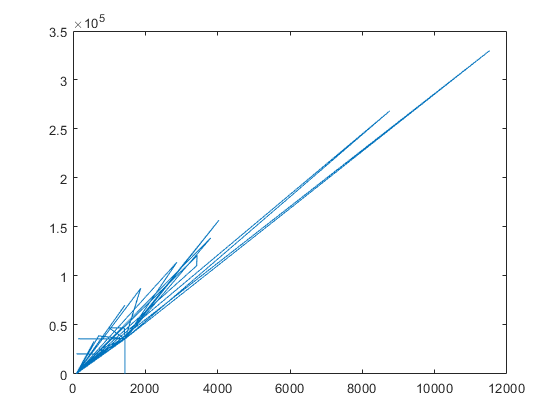

plot(satdata.Period,satdata.Altitude)

## Structures

A structure array is a data type that groups related data using data containers called *fields*. Each field can contain any data type. Structures use the same dot notation that tables do: `structName.fieldName.`

You can create a structure "by hand" with the function `struct`. 

S = struct('Name','Jean-Luc Picard','Rank','Captain','Age',55,'FantScore',300)

S = struct with fields:
         Name: 'Jean-Luc Picard'
         Rank: 'Captain'
          Age: 55
    FantScore: 300


S.Age

ans = 55

S(2) = struct('Name','William Riker','Rank','Commander','Age',38,'FantScore',340);
fieldnames(S)

ans = 4×1 cell array
    {'Name'     }
    {'Rank'     }
    {'Age'      }
    {'FantScore'}


S(2).FavGame = "Poker" 

S = 1×2 struct array with fields:
    Name
    Rank
    Age
    FantScore
    FavGame


S(1).FavGame


ans =

     []



But like most things it's easier to import data or *convert* from an already existing data holder

sats = table2struct(satdata)

sats = 1099×1 struct array with fields:
    Name
    Country
    Purpose
    Altitude
    Period
    Mass
    Year
    Lifetime


The table from the previous section is now a `struct.` Specifically, it is now a struct array, each element in this array can be thought of as a "record". We can index the struct array like any other array.

sats(2)

ans = struct with fields:
        Name: 'ABS-2'
     Country: 'NR'
     Purpose: 'Communications'
    Altitude: 35793
      Period: 1.4360e+03
        Mass: 6330
        Year: 2014
    Lifetime: 15


We can use dot notation with any of the elements like any other struct:

sats(200).Country

ans = 'USA'

We can get a list of field names:

f = fieldnames(sats)

f = 8×1 cell array
    {'Name'    }
    {'Country' }
    {'Purpose' }
    {'Altitude'}
    {'Period'  }
    {'Mass'    }
    {'Year'    }
    {'Lifetime'}


We can check if a struct has a certain field:

isfield(sats,f{3})

ans = logical
   1


isfield(sats,'Lifetime')

ans = logical
   1


isfield(sats,'donuts')

ans = logical
   0


Can treat the data in the struct like other arrays as well?:

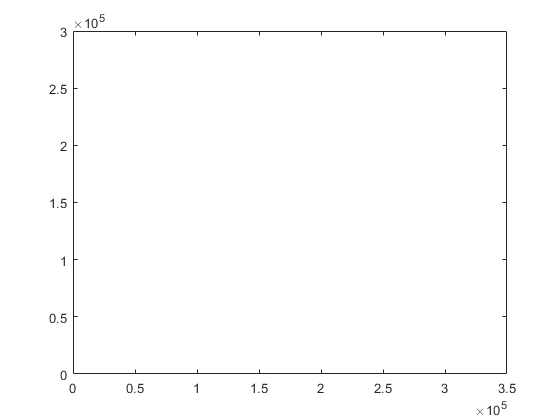

plot(sats.Period,sats.Altitude)

## Interesting use case for a Structure

You can store any type of data in a structure. Below is some code that shows how you can store similar data that naturally doesn't belong in a tabular format.

Im = load('flujet.mat') 

Im = struct with fields:
          X: [400×300 double]
        map: [64×3 double]
    caption: [2×32 char]


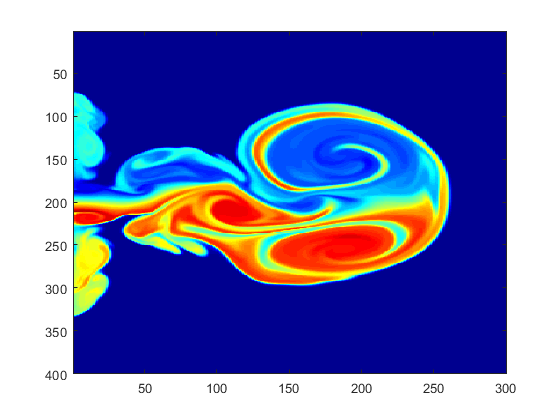

image(Im.X) 
colormap(Im.map)

Add to the structure called `Im`

Im(2) = load('cape.mat') 

Im = 1×2 struct array with fields:
    X
    map
    caption


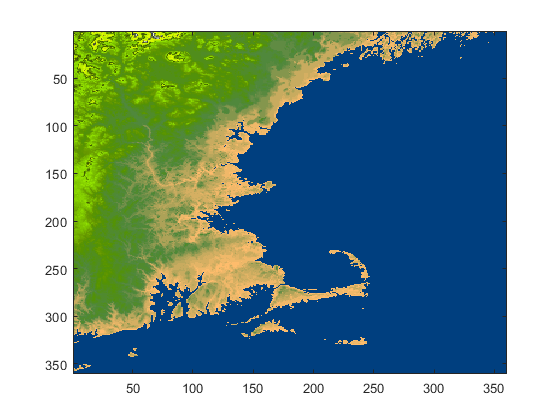

image(Im(2).X) 
colormap(Im(2).map)

Im(1).caption

ans = 2×32 char array
    'Astrophysical jet from NCSA.    '
    'One fluid collides with another.'


Im(2).caption

ans = 2×55 char array
    'NOAA altitude data for New England, including Cape Cod.'
    'Pseudocolor map uses blue for zero altitude.           '


string(Im(2).caption)

ans = 2×1 string array
    "NOAA altitude data for New England, including Cape Cod."
    "Pseudocolor map uses blue for zero altitude.           "


**Side Note: **This is the draw back of saving statements in a character array. Look at all the wasted space in the output above.

## Appendix: Relational and Logical Operators

- Data type:* Boolean*

- takes on logical values:  True(#) or False(0)

- Constructed from relational operators: `>`, `<`, `<=`, `>=`, `==`, `~=`

- Can string relational statements together with `&` or `|`

a = 13>5

a = logical
   1


b = [2 4 5 7 ];
c = [7 9 5 7 ];
b==c

ans = 1×4 logical array
   0   0   1   1


b~=c

ans = 1×4 logical array
   1   1   0   0


(4>5)&(1<9)

ans = logical
   0


4<5|1<9&9>10

ans = logical
   1


"yes"=="yes"

ans = logical
   1


There are also a number of built-in functions that compare arrays

A = [3 0 9 0 5 2];
all(A)

ans = logical
   0


any(A)

ans = logical
   1


find(A)

ans =      1     3     5     6


A>5

ans = 1×6 logical array
   0   0   1   0   0   0


find(A>4)

ans =      3     5


A(A>4)

ans =      9     5
